# Problema 5 - Tp7

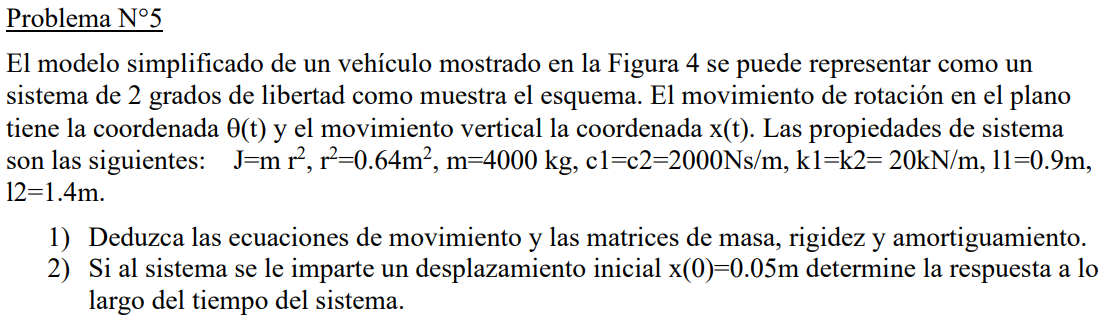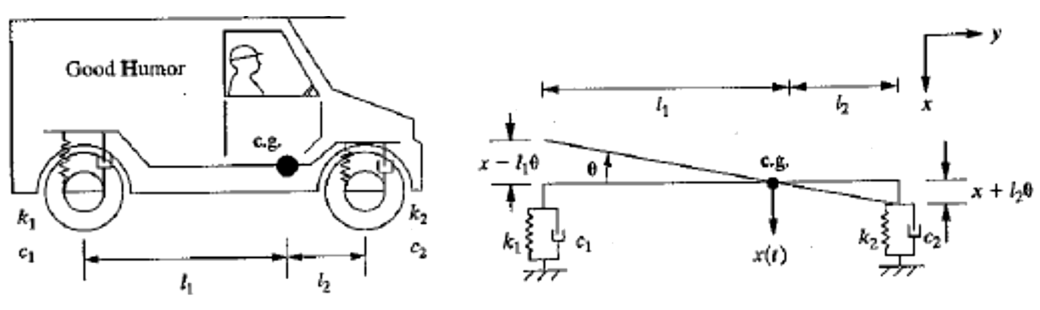

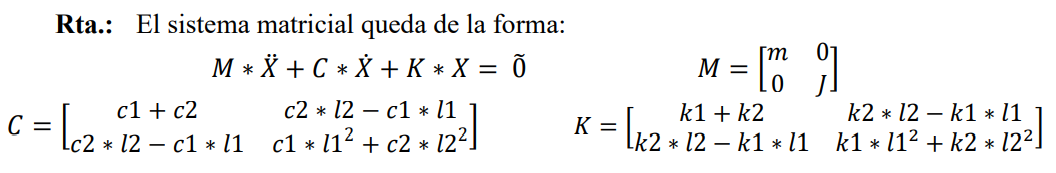

## Obtención de la matriz M, K y C

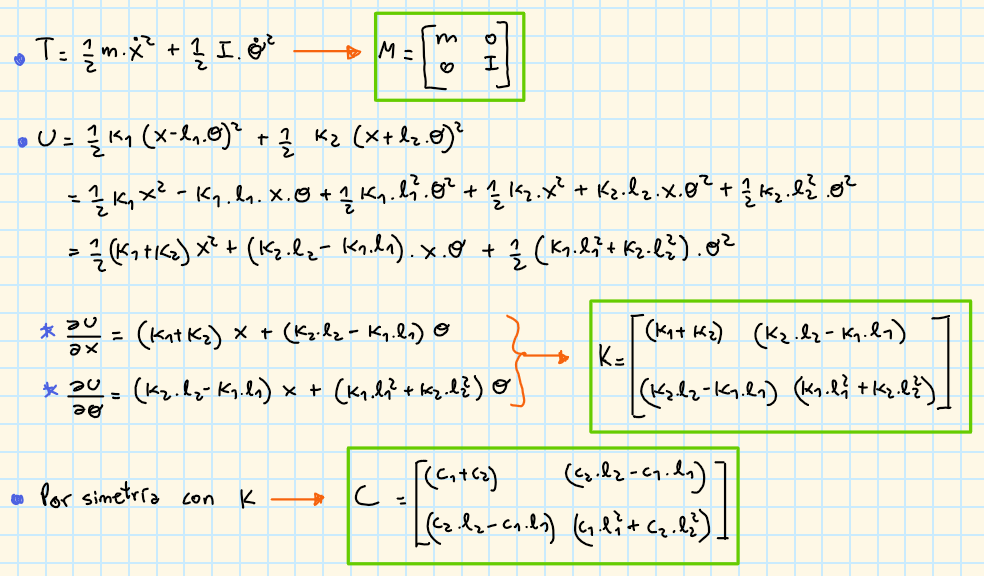

## Solución

clc; clear;

%% ---------------- DATOS DEL SISTEMA -----------------------
l1=0.9;
l2=1.4;

%Masas (seleccionadas de forma arbitraria, pero teniendo en cuenta que)
m=4000;
r=0.64;
I=m*r^2;

m1=m;
m2=I;
M = diag([m1,m2]);

%Rigidez
k=20000;
k1=k;
k2=k;
K = [k1+k2          k2*l2-k1*l1;
    k2*l2-k1*l1     k1*l1^2+k2*l2^2];

%Relacion de amortiguamiento crítico
%zitta = [0; 0]; esta vez no me dan el zitta, me dan C directamente
c=2000;
c1=c;
c2=c;
C = [c1+c2          c2*l2-c1*l1
    c2*l2-c1*l1     c1*l1^2+c2*l2^2];

%Condiciones iniciales
x0 = [0.05; 0]; %Desplazamientos iniciales
dx0 = [0; 0] ; %Velocidades iniciales

%Tiempo para graficar
tf=10;
dt=0.01;
t=0:dt:tf;


%% ------------------ AUTOVECTORES Y AUTOVALORES ------------------

[V,lambda] = eig(K,M);
w = diag(sqrt(lambda));


%% ----------------- MATRICES MODALES -----------------------------

Mmodal = round(V' * M * V);
Kmodal = round(V' * K * V);
%Cmodal = 2*zitta.*w.*eye(size(M));
Cmodal = round(V' * C * V);

zitta = diag(Cmodal./(2*w));         %Puedo calcular los zittas para cada modo de vibración usando esta fórmula (ChatGPT)

Y0 = V' * M * x0;                   %desplazamiento inicial en coordenadas modales
dY0 = V' * M * dx0;                 %velocidad inicial en coordenadas modales

%La ecuación diferencial a resolver es la siguiente:
%Mmodal*y''(t) + Cmodal*y'(t) + Kmodal*y(t) = 0

%%--------------RESOLUCIÓN EDO------------------------------------

%Ahora tengo un sistema del tipo Mmodal*y''+Kmodal*y=0 Como Mmodal y Kmodal
%son diagonales, es como si tuviera varias ecuaciones diferenciales
%simples.

%Para sistemas amortiguados, la solución es::
%

wd = w.*sqrt(1-zitta.^2); %frecuencia natural del sistema amortiguado
e=exp(1);

Y = zeros(length(w),length(t));

for i = 1:length(w)
    
    %Primer término
    Y(i,:) = e.^(-zitta(i)*w(i)*t).*( cos(wd(i)*t) + zitta(i)/sqrt(1-zitta(i)^2) * sin(wd(i)*t)).*Y0(i);
    
    %Segundo término
    Y(i,:) = Y(i,:)+ dY0(i) * (1/wd(i)*e.^(-zitta(i)*w(i)*t).*sin(wd(i)*t));
    
    %El tercer término no afecta porque es sólo si hay cargas externas
    %aplicadas
end

%Ahora paso de coordenadas modales a geométricas
X = V * Y;


%Analizo de x
X1max=max(X(1,:))

X1max = 0.0500



%Analizo la amplitud de theta
X2max=max(X(2,:))

X2max = 0.0095

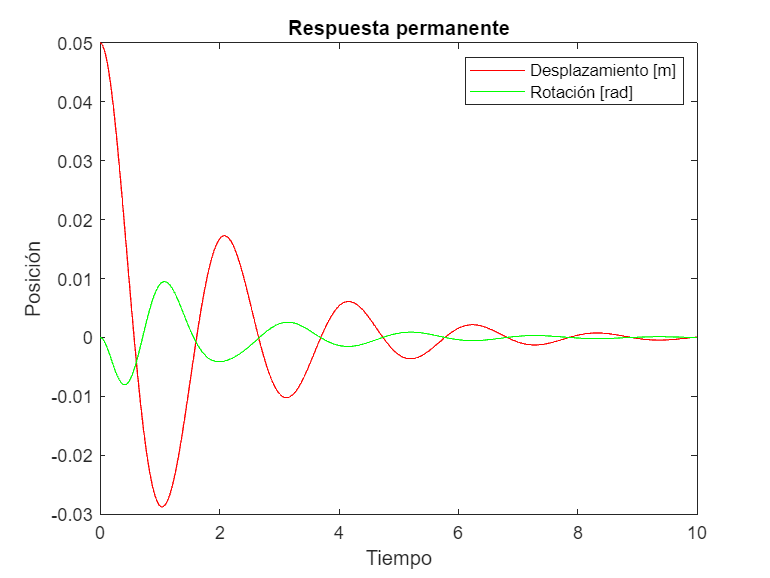



% Graficar las posiciones de las partículas
figure
plot(t, X(1,:), 'r', t, X(2,:), 'g');
xlabel('Tiempo');
ylabel('Posición');
legend('Desplazamiento [m]', 'Rotación [rad]');
title('Respuesta permanente');